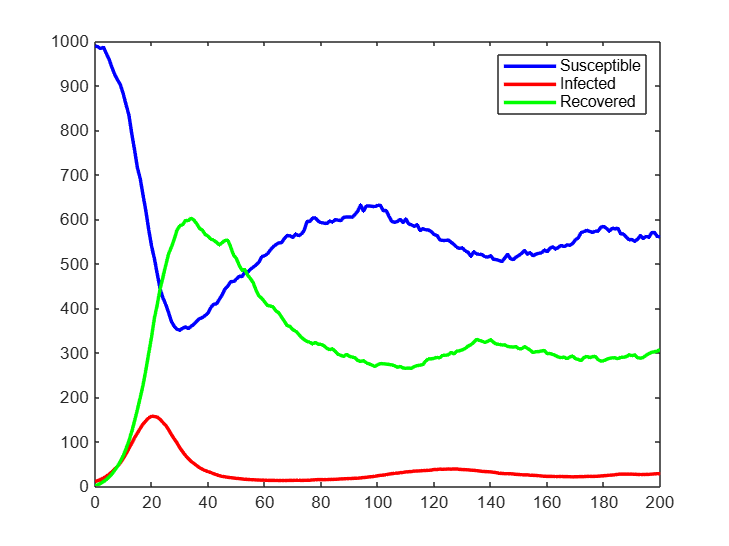

clear all
close all
clc



N = 1000;
dt=1;
y = 4; 
p=0.5;
%dt 4 bolsa
p = 0.5;
c = 1/dt;
L = 0.025/dt;
r = 0.275/dt;  
%dt 1 bolsa
%dt=1;
%c=5;
%r=1.1/4;
%L=0.1/4;

numsteps=200;     

sigma_S=0.01;  
sigma_I=0.01;  
sigma_R=0.01;  


I0=10;
S0=N-I0;
R0=0;


F = @(S,I,R)[-p*c*S*I/N+L*R;
                 p*c*S*I/N-r*I;
                 r*I-L*R];


x=zeros(3, numsteps+ 1);
x(:,1) =[S0;I0;R0];


for k= 1:numsteps
    curS= x(1, k);
    curI=x(2, k);
    curR=x(3, k);


    dX_det=F(curS,curI,curR); %* dt;

  
    dW_S=sqrt(dt)*randn;
    dW_I=sqrt(dt)*randn;
    dW_R=sqrt(dt)*randn;


    dS_stoch = sigma_S * curS * dW_S;
    dI_stoch = sigma_I * curI * dW_I;
    dR_stoch = sigma_R * curR * dW_R;
    x(1,k + 1) = curS + dX_det(1) + dS_stoch;
    x(2,k + 1) = curI + dX_det(2) + dI_stoch;
    x(3,k + 1) = curR + dX_det(3) + dR_stoch;
    x(1, k + 1) = max(x(1, k + 1), 0);
    x(2, k + 1) = max(x(2, k + 1), 0);
    x(3, k + 1) = max(x(3, k + 1), 0);
end


%figure('Position', [10, 200, 1200, 600])
plot(0:numsteps, x(1, :), 'b', 'MarkerSize', 10, 'LineWidth', 2)
hold on
plot(0:numsteps, x(2, :), 'r', 'MarkerSize', 10, 'LineWidth', 2)
plot(0:numsteps, x(3, :), 'g', 'MarkerSize', 10, 'LineWidth', 2)

legend('Susceptible', 'Infected', 'Recovered')

hold off